## Parameters

on_GPU = false;
T = 1; % sec
N = 10; % number of neurons
input_Hz = 50; % Hz
conn_strength_input2E = 1; % a.u.
conn_strength_E2E = 0; % a.u.
STDP_learning_rate_E2E = 0; % a.u. (STDP)

plot_synapses = true;
plot_Vm = true;
plot_spikes = true;
plot_refractoriness = true;
plot_weights = true;
plot_Hz = true;
plot_stimulation = true;
plot_STDP_traces = true;
plot_resource_pool = true;

## Run a single EI pool with

% Set up
tic
pool_single = RB_STDP_EI_pool( ...
    T, ...
    N, ...
    on_GPU, ...
    conn_strength_input2E, ...
    conn_strength_E2E, ...
    plot_synapses, ...
    plot_Vm, ...
    plot_spikes, ...
    plot_refractoriness, ...
    plot_weights, ...
    plot_Hz, ...
    plot_stimulation, ...
    plot_STDP_traces, ...
    plot_resource_pool ...
    );
pool_single.set_input( ...
    input_Hz ...
    );
toc

Elapsed time is 0.017446 seconds.


% Run
tStart = tic;
pool_single.run( ...
    false, ... % plot_during
    STDP_learning_rate_E2E ...
    );
tEnd = toc(tStart);
fprintf( ...
    'Elapsed time is %d minutes and %f seconds\n', ...
    floor(tEnd/60), ...
    rem(tEnd,60) ...
    );

Elapsed time is 0 minutes and 10.688317 seconds


% Finish
tic
pool_single.finish()
toc

Elapsed time is 0.001065 seconds.


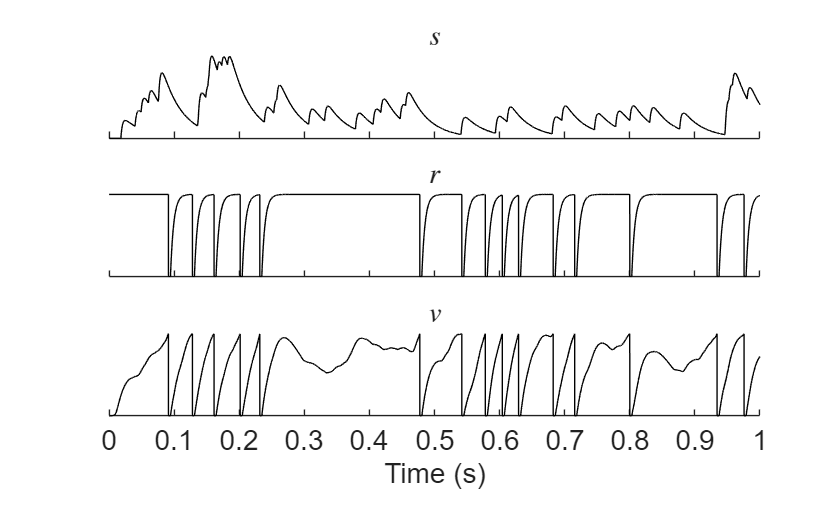

% Methods
fig1 = figure();
tiledlayout(3, 1)

% pool_single.synapses_input2E_t( ~any(pool_single.synapses_input2E_t,2), : ) = [];

hA = nexttile;
plot(pool_single.synapses_input2E_t', "black");
title("$s$", "Interpreter", "latex")
xticklabels([])
yticklabels([])
box(hA, "off")
set(get(hA, 'YAxis'), 'Visible', 'off');

hA = nexttile;
plot(pool_single.refractoriness_t(:, 10), "black");
title("$r$", "Interpreter", "latex")
xticklabels([])
yticklabels([])
box(hA, "off")
set(get(hA, 'YAxis'), 'Visible', 'off');

hA = nexttile;
plot(pool_single.Vm_t(:, 10), "black");
title("$v$", "Interpreter", "latex")
xlabel("Time (s)")
xticks(0:0.1 / pool_single.dt:pool_single.T / pool_single.dt)
xticklabels(0:0.1:pool_single.T)
yticklabels([])
box(hA, "off")
set(get(hA, 'YAxis'), 'Visible', 'off');

fontsize(fig1, 14, "points")
exportgraphics(gcf,'figures/paper/methods/neurons_and_synapses.pdf','ContentType','vector')

fig2 = figure();
ax2 = axes(fig2);
box off
axis off

hold on
plot(0:0.1:5, flip(exp(0:0.1:5)))
plot(-5:0.1:0, -exp(0:0.1:5)*0.18)
xticklabels([0])
xticks([0])
yticklabels([0])
yticks([0])
xline(0, "--")
yline(0, "--")
hold off

fontsize(fig1, 14, "points")

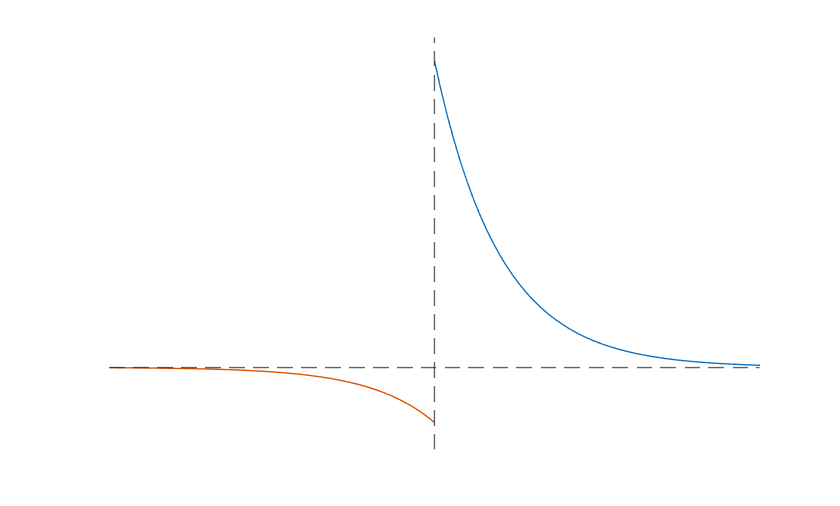

exportgraphics(gcf,'figures/paper/methods/STDP.pdf','ContentType','vector')